## 1.λt 及 Nt 随时间变化关系

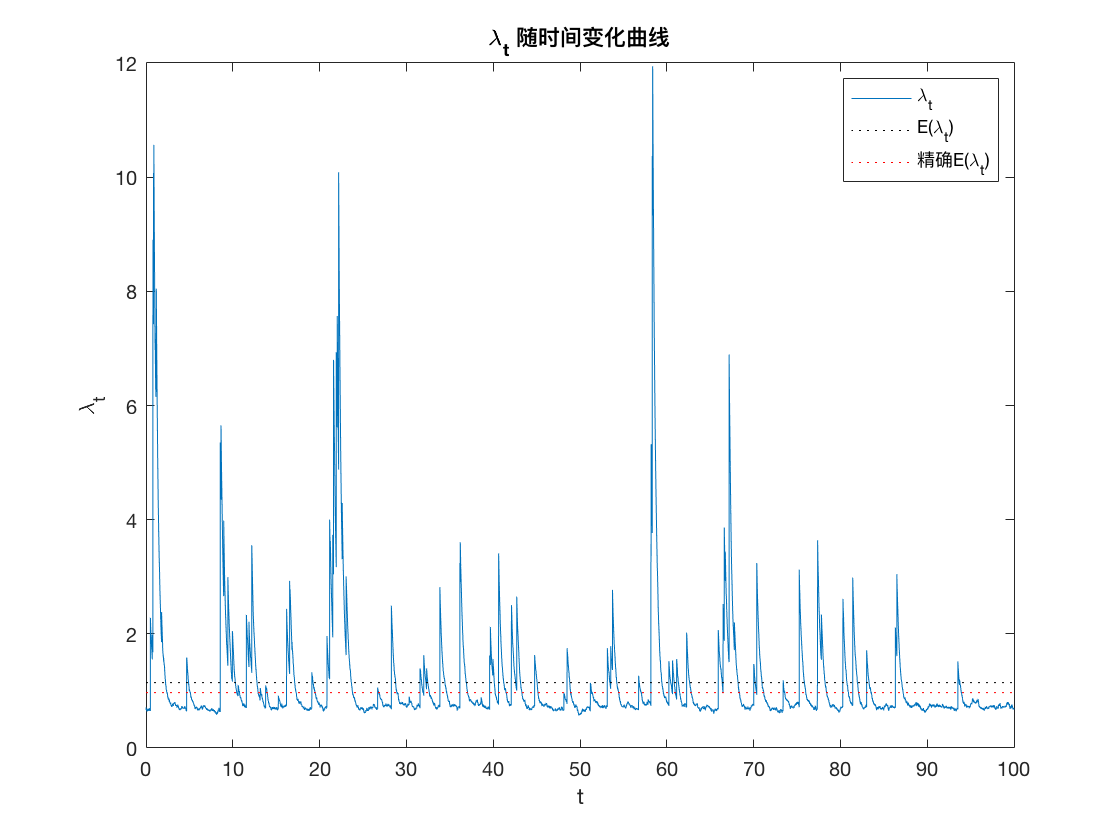

a = 3;    b = 0.7;    sigma = 0.1;    alpha = 1.2;    lambda0 = 0.7;    % 生成λ的相关参数
beta = 1;    X0 = 10;    c = 1.5;     % 生成Xt的相关参数
h = 0.01;    T = 100;    % 时间相关参数
% 生成λt并画图
[lambda,Nt] = Lambda_Generator(h,T,lambda0,a,b,sigma,alpha);
figure;
plot(0:h:T,lambda);    hold on;
plot([0,T],[mean(lambda),mean(lambda)],'k:');
plot([0,T],[a*b/(a-1/alpha),a*b/(a-1/alpha)],'r:');
legend({'\lambda_t','E(\lambda_t)','精确E(\lambda_t)'});
title('\lambda_t 随时间变化曲线');
xlabel('t');    ylabel('\lambda_t');

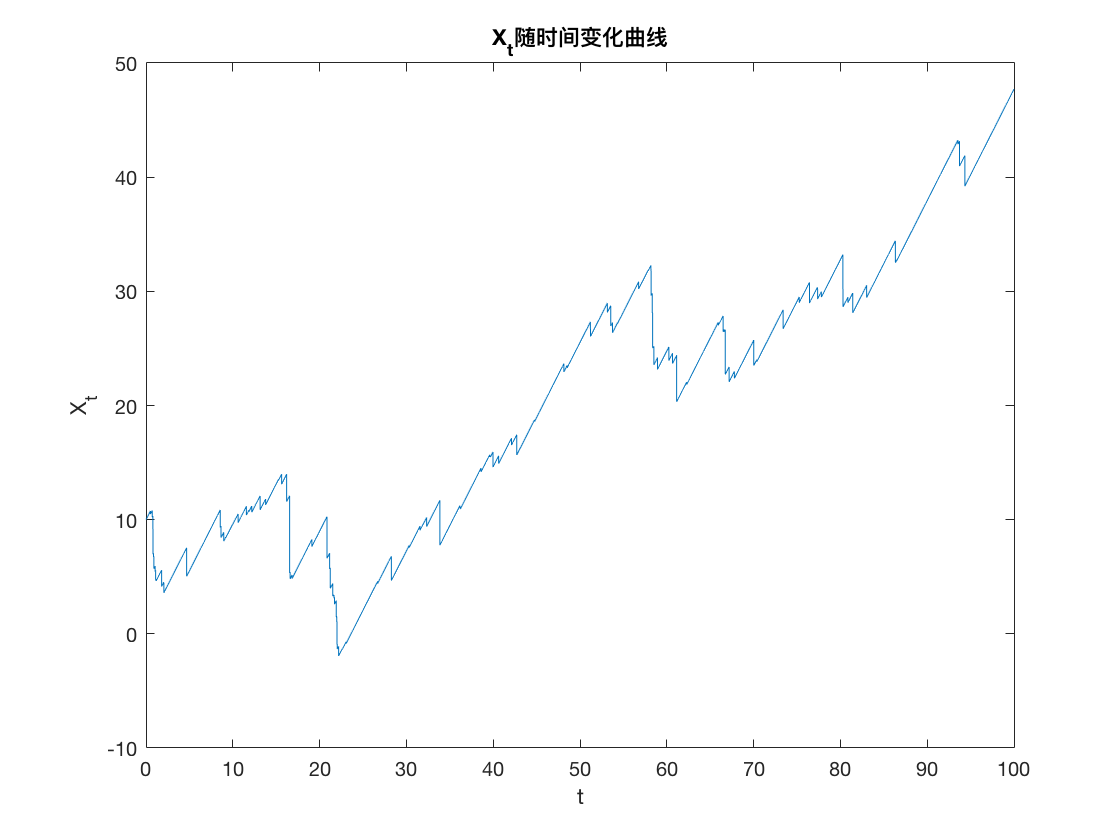

% 生成Xt并画图
pos = 1;    Ntlen = length(Nt);
Xt = zeros(1,floor(T/h)+1);    Xt(1) = X0;
J = floor(T/h);
for j = 1:J
    Xt(j+1) = Xt(j)+c*h;
    if pos <= Ntlen
        if j+1 == Nt(pos)
            pos = pos+1;
            Xt(j+1) = Xt(j+1)-exprnd(beta);
        end
    end
end
figure;
plot(0:h:T,Xt);    title('X_t随时间变化曲线');
xlabel('t');    ylabel('X_t');

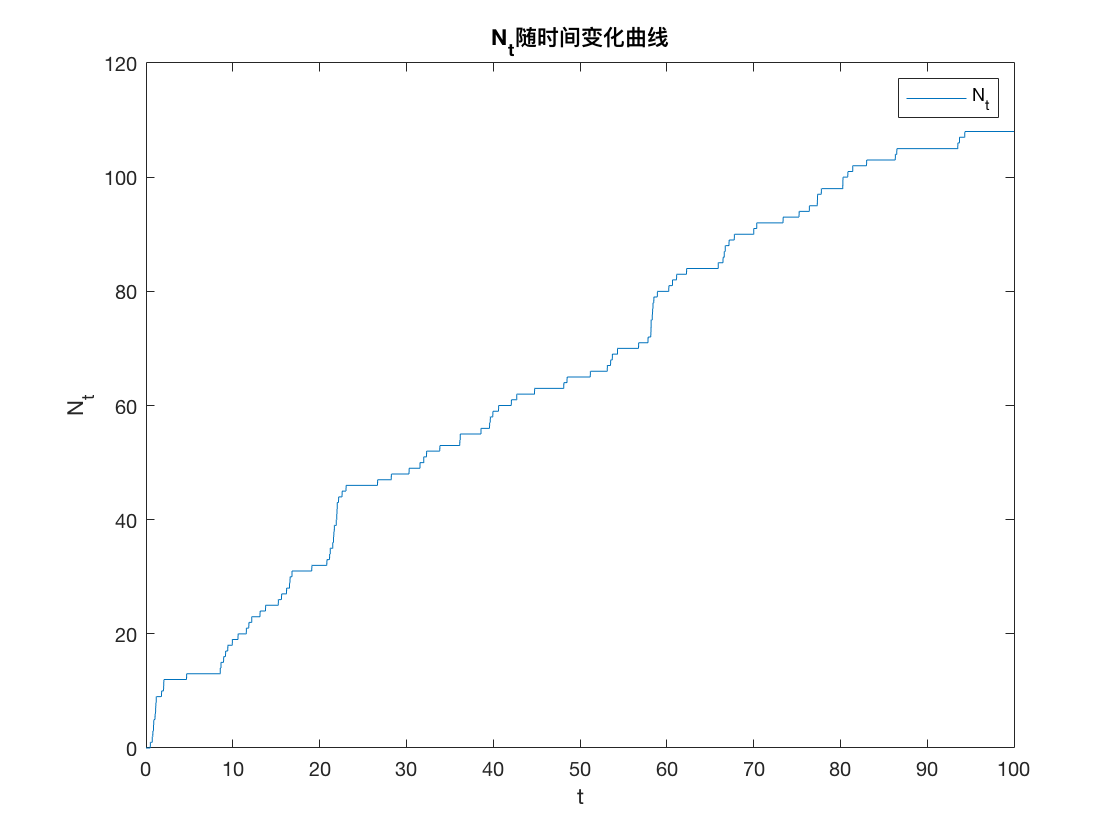

% 填充Nt并画图
Nts = zeros(1,Nt(1)-1);
for k = 1:Ntlen-1
    Nts = [Nts,k+zeros(1,Nt(k+1)-Nt(k))];
end
Nts = [Nts,Ntlen+zeros(1,J+1-Nt(Ntlen))];
figure;
plot(0:h:T,[0,Nts]);    title('N_t随时间变化曲线');
xlabel('t');    ylabel('N_t');    legend('N_{t}');

% figure;
% plot(0:h:T,[0,Nts],0:h:T,a*b/(a-1/alpha).*(0:h:T));    title('N_t随时间变化曲线');
% xlabel('t');    ylabel('N_t');    legend('N_{t}','E(N_t)');

## 2.模拟破产概率随时长变化时的情况, 观察平稳时长的范围

a = 3;    b = 0.7;    sigma = 0.1;    alpha = 1.5;    lambda0 = 0.7;    % 生成λ的相关参数
beta = 1;    X0 = 10;    c = 1.5;     % 生成Xt的相关参数
iter = 80;   step = 5;   % T的相关参数
h = 0.001;     % 时间相关参数
path = 1e4;  % 模拟次数
PT = zeros(iter,1);    PT1 = PT;
for k = 1:iter
    tic;
    Num = 0;    T = k*step;    J = floor(T/h);
    for i = 1:path
        [lambda,Nt] = Lambda_Generator(h,T,lambda0,a,b,sigma,alpha);    % 生成λt
        % 生成Xt
        pos = 1;    Xt = X0;    Ntlen = length(Nt);
        for j = 1:J
            Xt = Xt+c*h;
            if pos > Ntlen
                break;
            end
            if j+1 == Nt(pos)
                pos = pos+1;
                Xt = Xt-exprnd(beta);
            end
            if Xt <= 0
                Num = Num+1;    break;
            end
        end
    end
    PT1(k) = T;
    PT(k)  = Num/path;
    toc
end

Undefined function or variable 'Lambda_Generator'.

figure;
plot(0:step:iter*step,[0;PT],'k.');
% PT = [PT1,PT];
% for k = 1:iter
%     fprintf('%d\t%.2f%%\n',PT(k,1),PT(k,2)*100);
% end

## 3.模拟有限时间内破产概率随 λ0 变化时的变化情况

a = 3;    b = 0.7;    sigma = 0.1;    alpha = 1.5;    % 生成λ的相关参数, 不包含λ0
beta = 1;    X0 = 10;    c = 1.5;     % 生成Xt的相关参数
iter = 12;   step = 1;   % λ0的相关参数
h = 0.1;    T = 400;    % 时间相关参数
path = 1e4;  % 模拟次数
Plambda1 = zeros(iter,1);    Plambda2 = Plambda1;    Plambda3 = Plambda1;    Plambda = Plambda1;
% 求解参数 v 和 η
fun = @(x) [-c*x(1)+a*b*x(2);-a*x(2)+x(2)^2*sigma^2/2+alpha*beta/(alpha-x(2))/(beta-x(1))-1];
y = fsolve(fun,[1/2,1/2]);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the default value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



v = y(1);    eta = y(2);
% Q测度下相应参数
aTran = a-eta*sigma^2;
bTran = a*b*(1+a*eta-eta^2*sigma^2/2)/(a-eta*sigma^2);
sigmaTran = sigma*sqrt(1+a*eta-eta^2*sigma^2/2);
alphaTran = (alpha-eta)/(1+a*eta-eta^2*sigma^2/2);
betaTran = beta-v;
m = eta/(1+a*eta-eta^2*sigma^2/2);
Plambda4 = Plambda1;
parfor k = 1:iter
    tic;
    % P测度下破产概率
    lambda0 = k*step;    Num = 0;    J = floor(T/h);
    for i = 1:path
        [~,Nt] = Lambda_Generator(h,T,lambda0,a,b,sigma,alpha);    % 生成Nt
        % 生成Xt
        pos = 1;    Xt = X0;    Ntlen = length(Nt);
        for j = 1:J
            Xt = Xt+c*h;
            if pos > Ntlen
                break;
            end
            if j+1 == Nt(pos)
                pos = pos+1;
                Xt = Xt-exprnd(beta);
            end
            if Xt <= 0
                Num = Num+1;    break;
            end
        end
    end
    Plambda(k)  = lambda0;
    Plambda1(k) = Num/path;
    Plambda2(k) = exp(eta*lambda0-v*X0);
    Plambda3(k) = exp(eta*lambda0-v*X0)*(beta-v)/beta;
    
    % Q测度下破产概率
    lambda0Tran = lambda0*(1+a*eta-eta^2*sigma^2/2);
    lambdatau = zeros(1,path);
    for i = 1:path
        [lambda,Nt] = Lambda_Generator(h,T,lambda0Tran,aTran,bTran,sigmaTran,alphaTran);    % 生成λt,Nt
        % 生成Xt
        pos = 1;    Xt = X0;    Ntlen = length(Nt);
        for j = 1:J
            Xt = Xt+c*h;
            if pos > Ntlen
                break;
            end
            if j+1 == Nt(pos)
                pos = pos+1;
                Xt = Xt-exprnd(betaTran);
            end
            if Xt <= 0
                lambdatau(i) = lambda(j);    break;
            end
        end
    end
    Plambda4(k) = exp(m*lambdaTran-v*X0)*(beta-v)/beta*(alpha-eta)/alpha*mean(exp(-m.*lambdatau));
    toc
end

Starting parallel pool (parpool) using the 'local' profile ...
connected to 4 workers.

Plambda = [Plambda,Plambda1,Plambda2,Plambda3,Plambda4];
% 输出破产概率
for k = 1:iter
    fprintf('%d\t%.2f%%\t%.2f%%\t%.2f%%\t%.2f%%\n',Plambda(k,1),...
        Plambda(k,2)*100,Plambda(k,3)*100,Plambda(k,4)*100,Plambda(k,5)*100);
end

## 4.模拟有限时间内破产概率随 X0 变化时的变化情况

a = 3;    b = 0.7;    sigma = 0.1;    alpha = 1.5;    lambda0 = 0.7;    % 生成λ的相关参数, 不包含λ0
beta = 1;    c = 1.5;     % 生成Xt的相关参数
iter = 10;   step = 1;   % X0的相关参数
h = 0.01;    T = 200;    % 时间相关参数
path = 1e4;  % 模拟次数
PX1 = zeros(iter,1);    PX2 = PX1;    PX3 = PX1;    PX = PX1;
J = floor(T/h);
% 求解参数 v 和 η
fun = @(x) [-c*x(1)+a*b*x(2);-a*x(2)+x(2)^2*sigma^2/2+alpha*beta/(alpha-x(2))/(beta-x(1))-1];
y = fsolve(fun,[1/2,1/2]);
v = y(1);    eta = y(2);
% Q测度下相应参数
aTran = a-eta*sigma^2;    bTran = a*b*(1+a*eta-eta^2*sigma^2/2)/(a-eta*sigma^2);
sigmaTran = sigma*sqrt(1+a*eta-eta^2*sigma^2/2);
alphaTran = (alpha-eta)/(1+a*eta-eta^2*sigma^2/2);    betaTran = beta-v;
m = eta/(1+a*eta-eta^2*sigma^2/2);
PX5 = PX1;
parfor k = 1:iter
    tic;
    % P测度下破产概率
    X0 = 4+k*step;    Num = 0;
    for i = 1:path
        [~,Nt] = Lambda_Generator(h,T,lambda0,a,b,sigma,alpha);    % 生成Nt
        % 生成Xt
        pos = 1;    Xt = X0;    Ntlen = length(Nt);
        for j = 1:J
            Xt = Xt+c*h;
            if pos > Ntlen
                break;
            end
            if j+1 == Nt(pos)
                pos = pos+1;
                Xt = Xt-exprnd(beta);
            end
            if Xt <= 0
                Num = Num+1;    break;
            end
        end
    end
    PX(k)  = X0;
    PX1(k) = Num/path;
    PX2(k) = exp(eta*lambda0-v*X0);
    PX3(k) = exp(eta*lambda0-v*X0)*(beta-v)/beta;
    
    % Q测度下破产概率
    lambda0Tran = lambda0*(1+a*eta-eta^2*sigma^2/2);
    lambdatau = zeros(1,path);
    for i = 1:path
        [lambda,Nt] = Lambda_Generator(h,T,lambda0Tran,aTran,bTran,sigmaTran,alphaTran);    % 生成λt,Nt
        % 生成Xt
        pos = 1;    Xt = X0;    Ntlen = length(Nt);
        for j = 1:J
            Xt = Xt+c*h;
            if pos > Ntlen
                break;
            end
            if j+1 == Nt(pos)
                pos = pos+1;
                Xt = Xt-exprnd(betaTran);
            end
            if Xt <= 0
                lambdatau(i) = lambda(j);    break;
            end
        end
    end
    PX5(k) = exp(m*lambdaTran-v*X0)*(beta-v)/beta*(alpha-eta)/alpha*mean(exp(-m.*lambdatau));
    toc
end
PX = [PX,PX1,PX2,PX3,PX4];
% 输出破产概率
for k = 1:iter
    fprintf('%d\t%.2f%%\t%.2f%%\t%.2f%%\t%.2f%%\n',PX(k,1),...
        PX(k,2)*100,PX(k,3)*100,PX(k,4)*100,PX(k,5)*100);
end

## 5.$\mu_1,\lambda_1,\lambda_2,N_{1t},N_{2t}$随时间变化的曲线

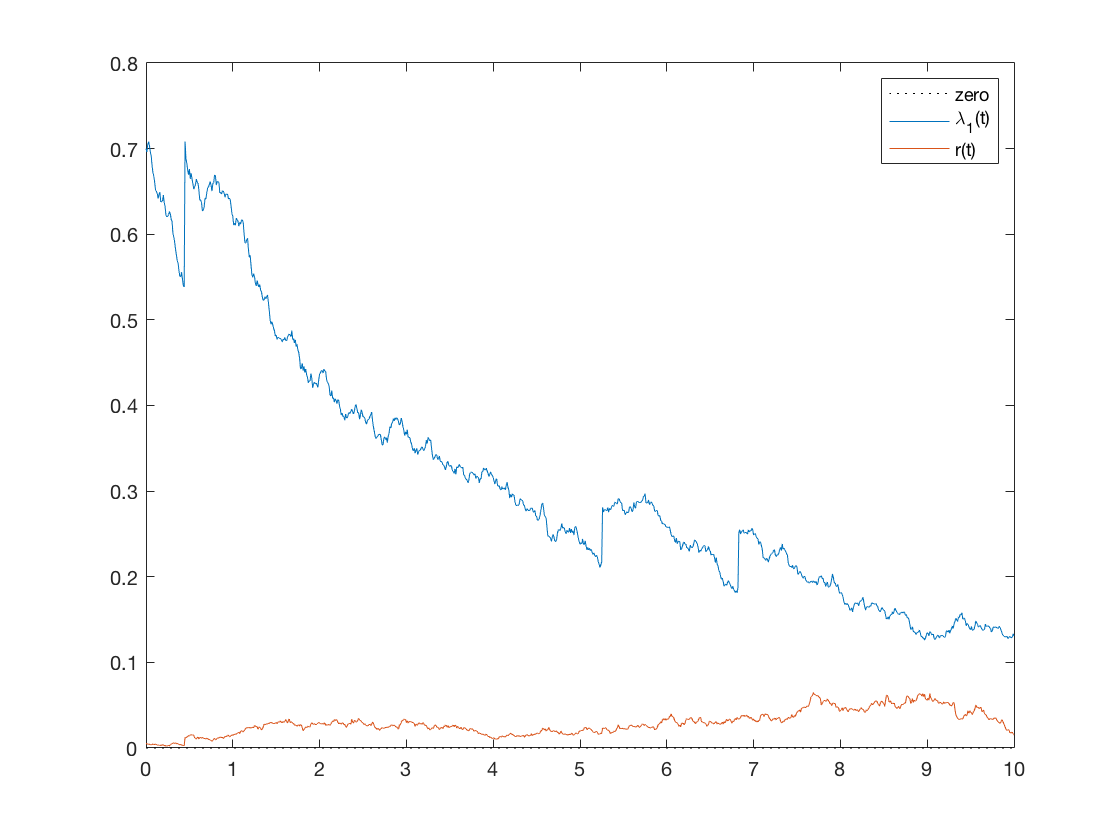

a1lambda1 = 0.04;    a2lambda1 = -0.3;    b1lambda1 = 0;    b2lambda1 =0.005;
a1lambda2 = 0.03;    a2lambda2 = -0.7;
a1r = 0.005;    a2r = -0.3;    b1r = 0;    b2r = 0.009;
a1mu = 0.05;   a2mu = -0.5;   b1mu = 0;   b2mu = 0.025;
Ybeta = 0.1;    Vbeta = 0.5;    Zbeta = 0.01;    Xbeta = 0.02;    Ubeta = 0.01;
h = 0.01;      T = 10;    J = floor(T/h);
lambda10 = 0.7;    lambda20 = 1;    r0 = 0.005;    mu0 = 0.01;
[lambda1,N1t] = Lambda1_Generator(h,T,lambda10,a1lambda1,a2lambda1,b1lambda1,b2lambda1,Ybeta);
[lambda2,N2t] = Lambda2_Generator(h,T,lambda20,a1lambda2,a2lambda2,Vbeta);
r = R_Generator(h,T,r0,a1r,a2r,b1r,b2r,Zbeta,N1t);
mu = Mu_Generator(h,T,mu0,a1mu,a2mu,b1mu,b2mu,Xbeta,Ubeta,N1t,N2t);

% λ1, λ2, mu随时间变化曲线
figure;
plot([0,T],[0,0],'k:');    hold on;
plot(0:h:T,[lambda1',r']);
legend('zero','\lambda_1(t)','r(t)');

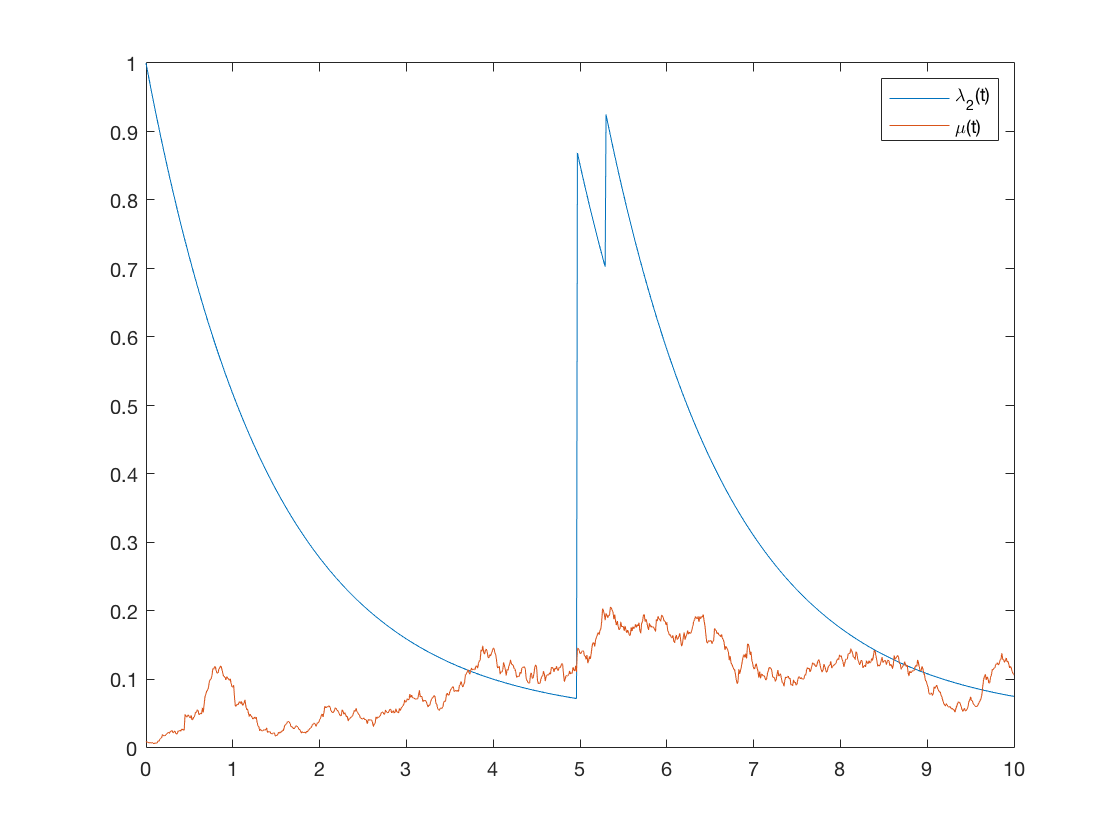

figure;
plot(0:h:T,[lambda2',mu']);
legend('\lambda_2(t)','\mu(t)');

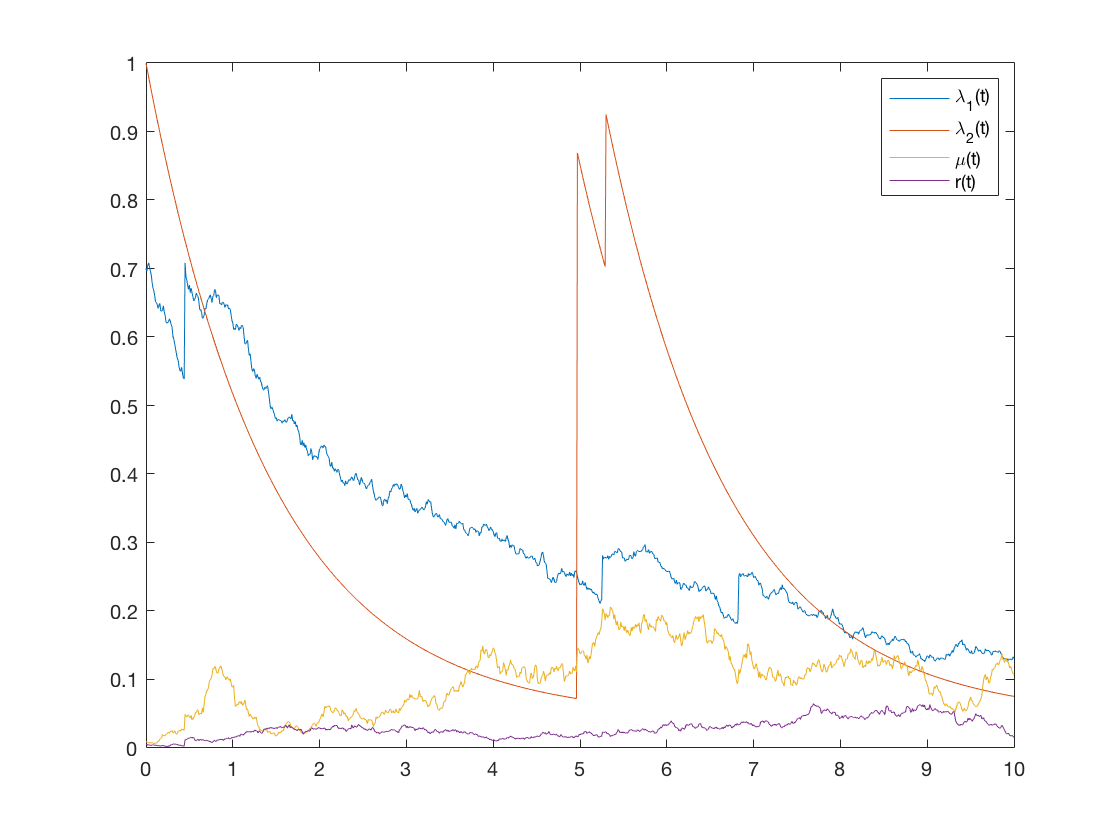

figure;
plot(0:h:T,[lambda1',lambda2',mu',r']);
legend('\lambda_1(t)','\lambda_2(t)','\mu(t)','r(t)');

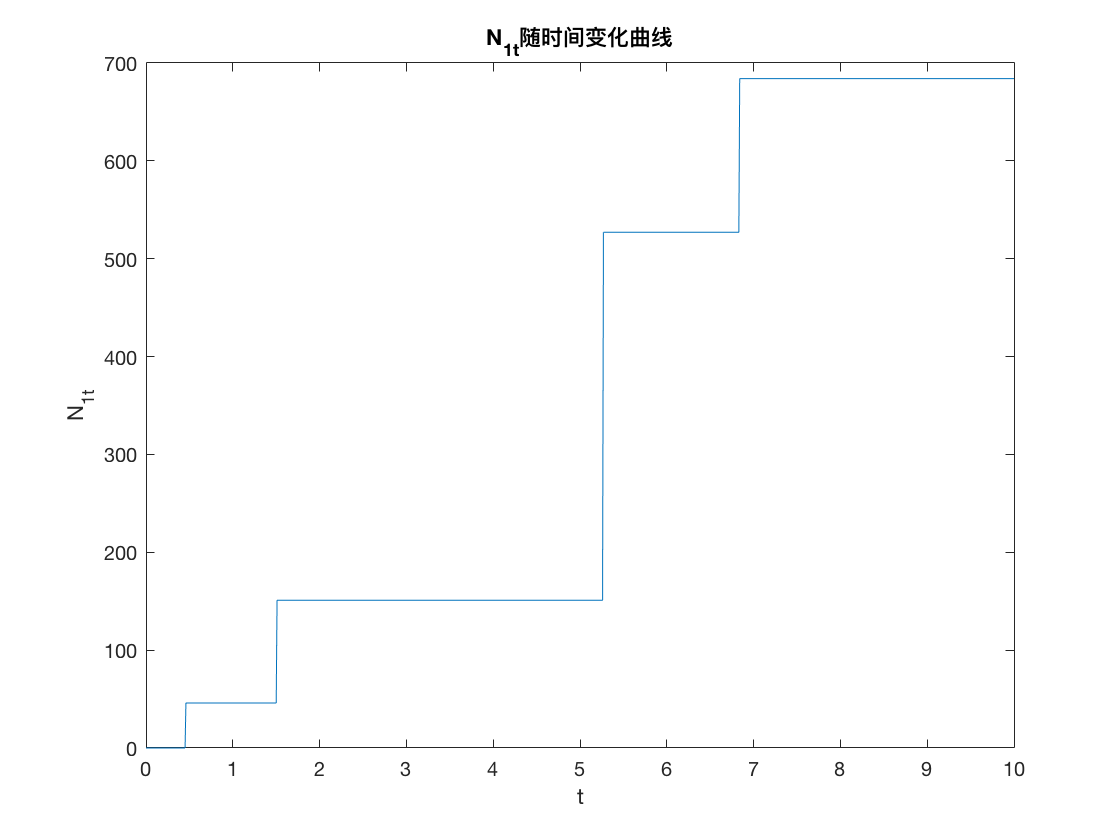

% 填充Nt并画图
Nts = zeros(1,N1t(1)-1);    N1tlen = length(N1t);
for k = 1:N1tlen-1
    Nts = [Nts,N1t(k)+zeros(1,N1t(k+1)-N1t(k))];
end
Nts = [Nts,N1t(N1tlen)+zeros(1,J+1-N1t(N1tlen))];
figure;
plot(0:h:T,[0,Nts]);    title('N_{1t}随时间变化曲线');
xlabel('t');    ylabel('N_{1t}');

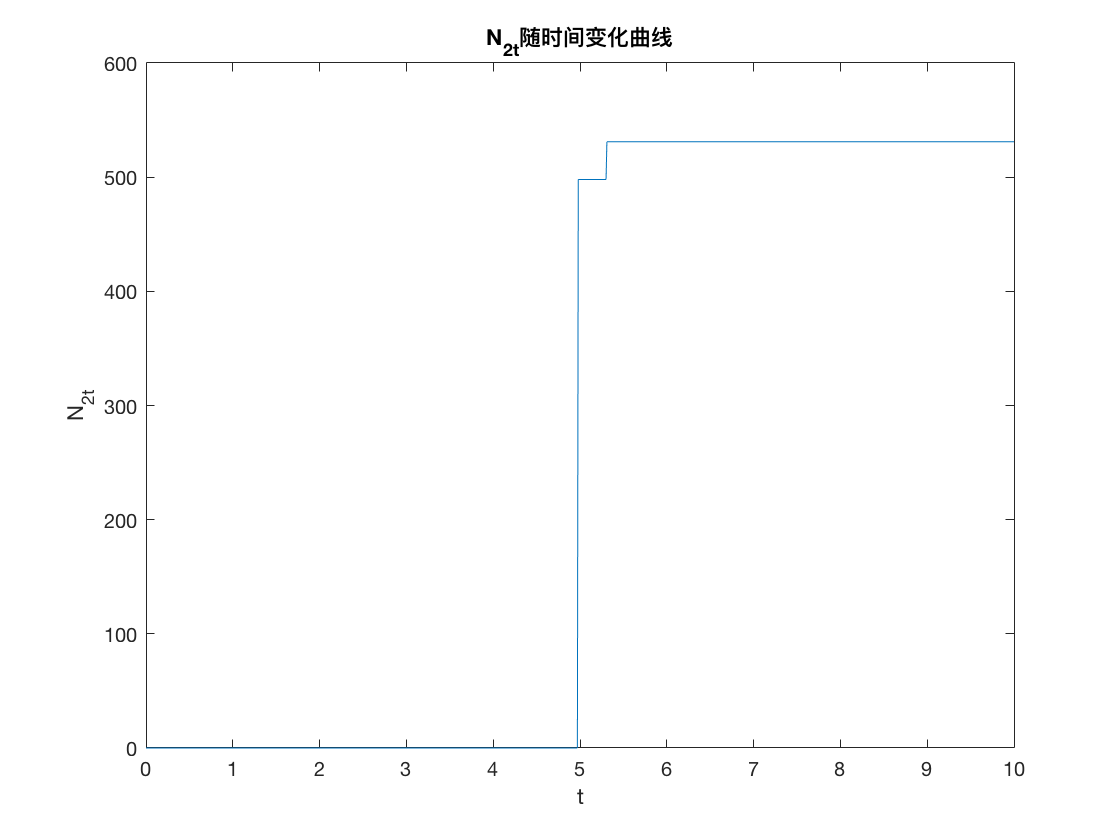


Nts = zeros(1,N2t(1)-1);    N2tlen = length(N2t);
for k = 1:N2tlen-1
    Nts = [Nts,N2t(k)+zeros(1,N2t(k+1)-N2t(k))];
end
Nts = [Nts,N2t(N2tlen)+zeros(1,J+1-N2t(N2tlen))];
figure;
plot(0:h:T,[0,Nts]);    title('N_{2t}随时间变化曲线');
xlabel('t');    ylabel('N_{2t}');

## 6.长寿债券随时间变化的图像

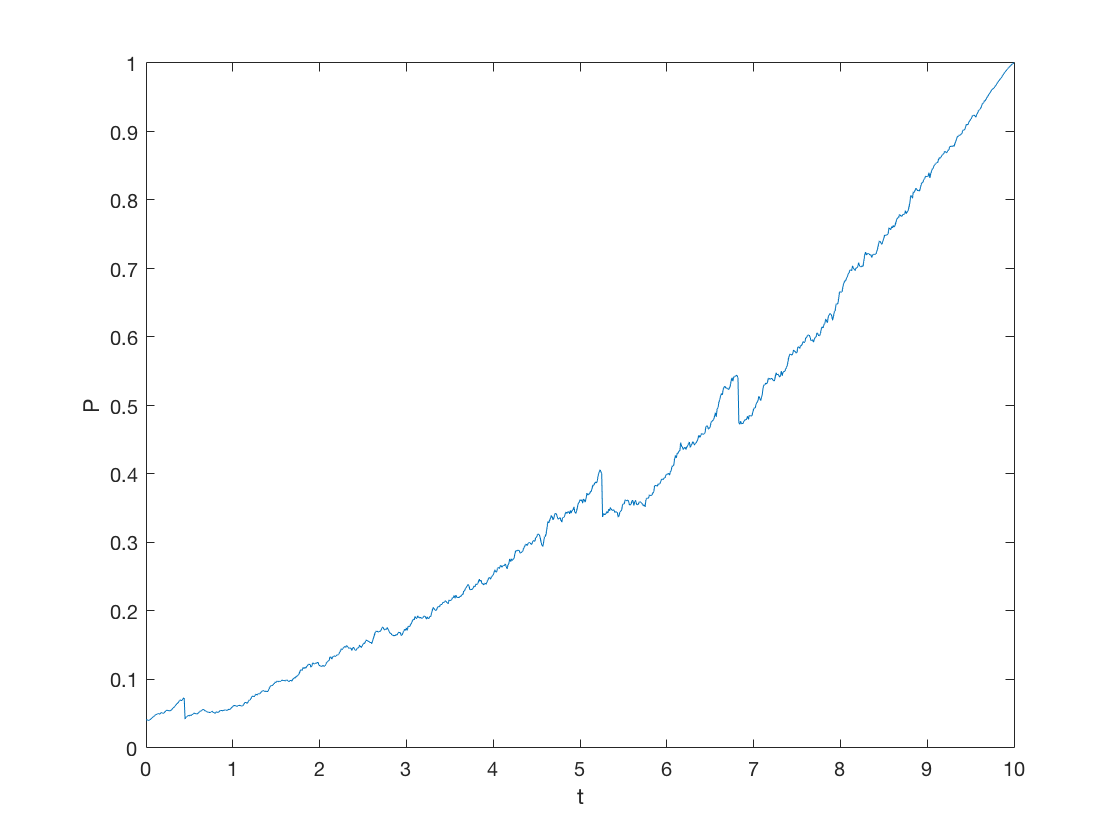

% a1lambda1 = 0.04;    a2lambda1 = 1;    b1lambda1 = -0.01;    b2lambda1 = 0.01;
% a1lambda2 = 0.03;    a2lambda2 = -0.1;
% a1r = 0.005;    a2r = -0.1;    b1r = -0.02;    b2r = 0.04;
% a1mu = 0.05;   a2mu = 0.2;   b1mu = 0;   b2mu = 0.025;
% Ybeta = 1.5;    Vbeta = 2;    Zbeta = 0.03;    Xbeta = 0.05;    Ubeta = 0.03;
% h = 0.001;      T = 10;    J = floor(T/h);
% lambda10 = 1;    lambda20 = 0.7;    r0 = 0.005;    mu0 = 0.01;
% [lambda1,N1t] = Lambda1_Generator(h,T,lambda10,a1lambda1,a2lambda1,b1lambda1,b2lambda1,Ybeta);
% [lambda2,N2t] = Lambda2_Generator(h,T,lambda20,a1lambda2,a2lambda2,Vbeta);
% r = R_Generator(h,T,r0,a1r,a2r,b1r,b2r,Zbeta,N1t);
% mu = Mu_Generator(h,T,mu0,a1mu,a2mu,b1mu,b2mu,Xbeta,Ubeta,N1t,N2t);
load('mortalitynum1.mat');
tspan = 0:h:T;    y0 = zeros(1,7);
[~,y] = ode113(@(x,y) dydx7(y,a1lambda1,a2lambda1,a1lambda2,a2lambda2,...
    a1r,a2r,a1mu,a2mu,b1lambda1,b2lambda1,b1r,b2r,b1mu,b2mu,Ybeta,Xbeta,Zbeta,Ubeta,Vbeta), tspan, y0);
y = flipud(y);     A = y(:,1);        B = y(:,2);        C = y(:,3);
Aquta = y(:,4);    Bquta = y(:,5);    Cquta = y(:,6);    Dquta = y(:,7);
S = exp(Aquta+mu'.*Bquta+lambda1'.*Cquta+lambda2'.*Dquta);
P = exp(A+r'.*B+lambda1'.*C);
figure;
plot(tspan,P);
xlabel('t');    ylabel('P');

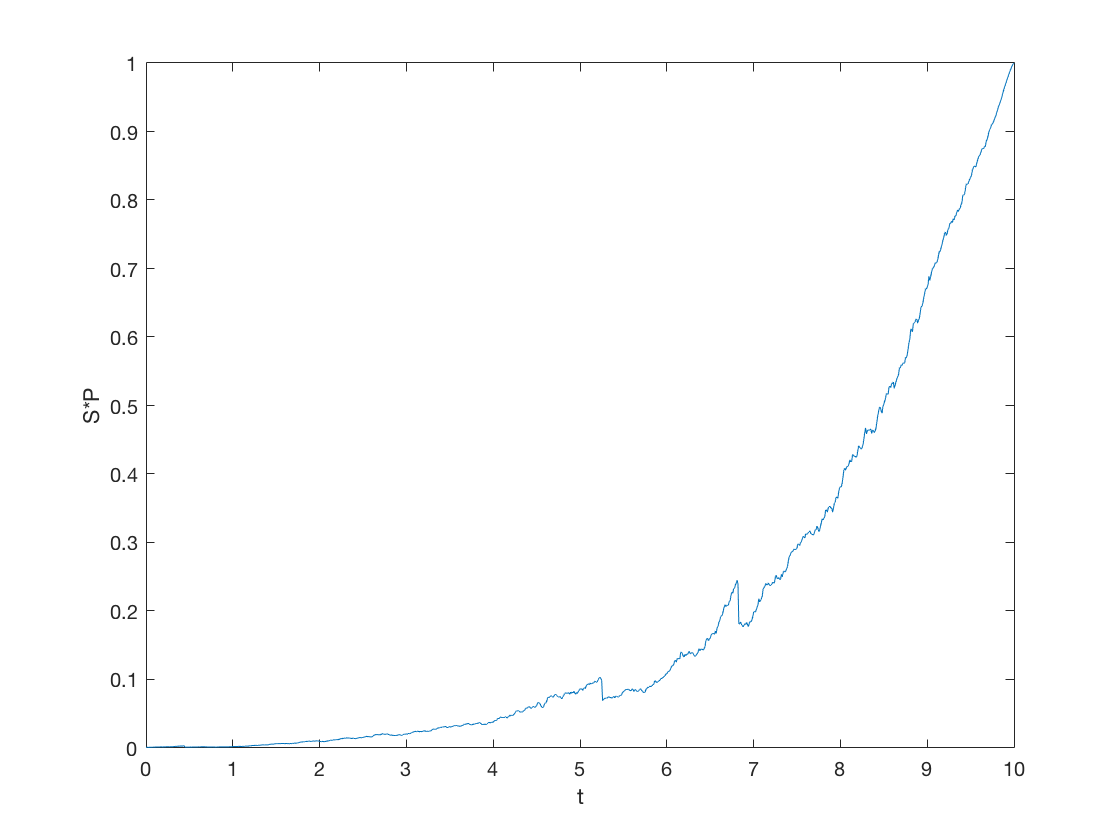

figure;
plot(tspan,S.*P);
xlabel('t');    ylabel('S*P');